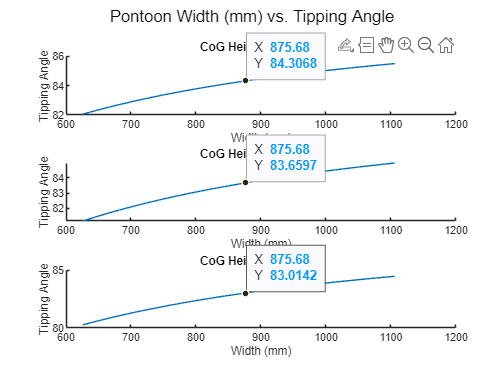

h = 43.65;
curr_w = 875.68;

starting_w = curr_w - 250;
ending_w = curr_w + 250;
iterations = 25;
w_step = round((ending_w - starting_w)/iterations);
h_step = 5;
w = zeros(iterations,3);
theta = zeros(iterations,3);
curr_theta=zeros(1,3);

for n = 1:3
    for i = 1:iterations
        w(i,n) = starting_w + (i-1)*w_step;
        theta(i,n) = rad2deg(atan(w(i)/2/(h+(n-1)*h_step)));
    end
    curr_theta(n) = rad2deg(atan(curr_w/2/(h+(n-1)*h_step)));
end



subplot(3,1,1);
hold on
plot(w(:,1),theta(:,1));
p1 = plot(curr_w,curr_theta(1),'r*');
title("CoG Height: 43.65mm");
xlabel("Width (mm)");
ylabel("Tipping Angle");
datatip(p1,curr_w,curr_theta(1));
hold off

subplot(3,1,2);
hold on
plot(w(:,2),theta(:,2));
p2 = plot(curr_w,curr_theta(2),'r*');
title("CoG Height: 48.65mm");
xlabel("Width (mm)");
ylabel("Tipping Angle");
datatip(p2,curr_w,curr_theta(2));
hold off

subplot(3,1,3);
hold on
plot(w(:,3),theta(:,3))
p3 = plot(curr_w,curr_theta(3),'r*');
title("CoG Height: 53.65mm");
xlabel("Width (mm)");
ylabel("Tipping Angle");
datatip(p3,curr_w,curr_theta(3));
hold off

sgtitle("Pontoon Width (mm) vs. Tipping Angle");